%% import circuitlab data
clabfile='/Users/madi/Documents/GitHub/MATLAB/Final Project/Milestone 2/Freq Domain (1).csv';
clabdata=readmatrix(clabfile);

%% circuitlab frequency
clabfreq=clabdata(:,1);
clabfreq=clabfreq.*2.*pi;

%% circuitlab gain
clabgain=clabdata(:,2);

%% circuitlab phase shift 
clabphase=clabdata(:,3);

subplot(2,1,1)
grid on
hold on
plot(clabfreq,clabgain,'DisplayName','CircuitLab')
hold on
% plot(f, G,'DisplayName','Bode Data')
% semilogx(bafreq,bagain,'DisplayName','Bode Analyzer')
hold on

ylabel('Magnitude (dB)')
title ('Bode Diagram')
legend('Theoretical','Circuit Lab','Bode Data')

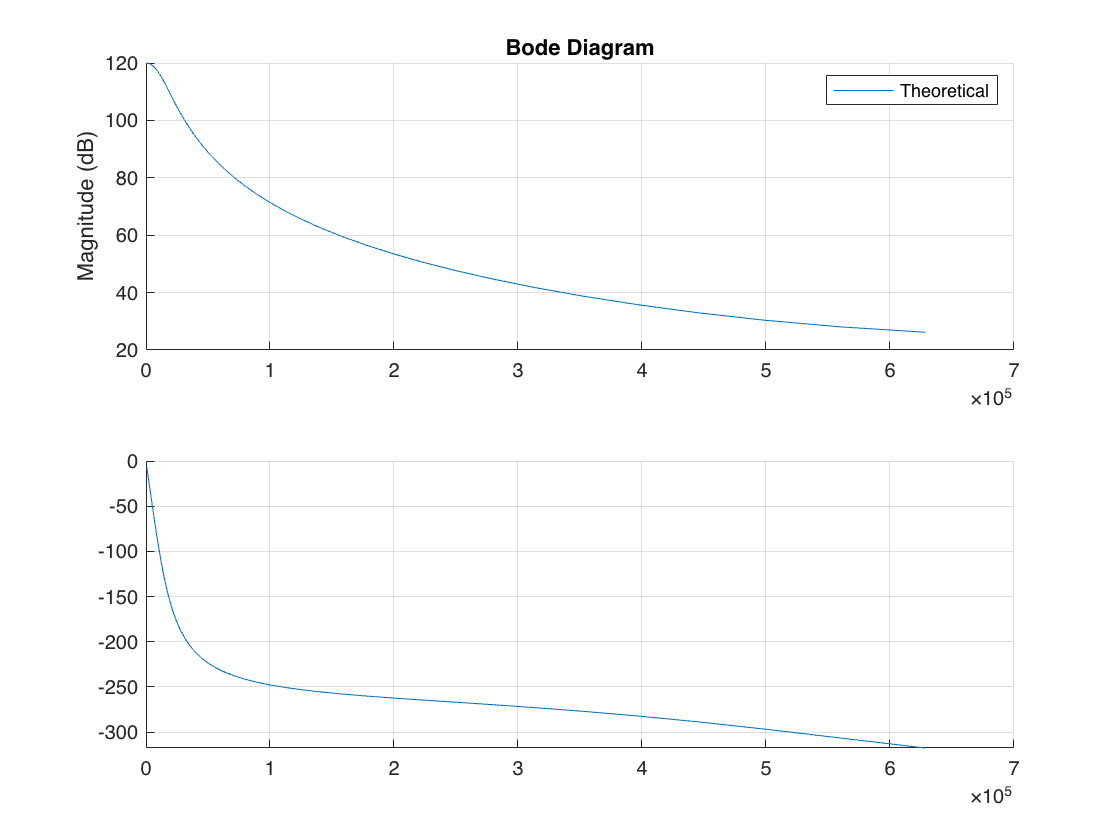

hold off



subplot(2,1,2)
grid on
hold on
plot(clabfreq,clabphase,'DisplayName','CircuitLab')
hold on

% plot(f, theta,'DisplayName','Bode Data') % Data file from lab
semilogx(bafreq,baphase,'DisplayName','Bode Analyzer')

Unrecognized function or variable 'bafreq'.


hold on

ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')
legend('Theoretical','Circuit Lab','Bode Data')
hold off
